%% ===============================================================
%  Triplicate substrate consumption analysis with SE reporting
%  - Runs analyze_one_rep.m on 3 replicate CSVs
%  - Prints mean ± SE (n=3)
%  - Saves replicate-wise and summary CSVs
% ===============================================================
clf; clear;

%3 .csv replicate files, time:OD_baseline:OD_value:FLC_baseline:FLC_value 
files = {

};
nReps = numel(files);

% --- Fixed-schema template to avoid struct mismatch ---
% --- Fixed-schema template to avoid struct mismatch ---
template = struct( ...
    'tau_ncc', NaN, ...
    'tau_deriv', NaN, ...
    'lead_half', NaN, ...
    'avg_rate_sg_mean', NaN, ...
    'avg_rate_sg', NaN, ...
    'avg_rate_spline', NaN, ...
    'avg_rate_spline_int', NaN, ...
    'peak_rate_sg', NaN, ...
    't_peak_center', NaN, ...
    't_peak_start', NaN, ...
    't_peak_end', NaN, ...
    'n_masked_ratio', NaN, ...
    'frac_masked_ratio', NaN, ...
    'first_valid_ratio_time', NaN, ...
    ... % ===== New numeric fields for plotting =====
    't_series', [], ...
    'OD_corr_s', [], ...
    'Flc_corr_s', [], ...
    'OD_norm', [], ...
    'Flc_norm', [], ...
    't_half_OD', NaN, ...
    't_half_Flc', NaN ...
);

results = repmat(template, nReps, 1);

% Sanity check helper (anonymous): compare field sets
checkFields = @(A,B) isequal(sort(fieldnames(A)), sort(fieldnames(B)));


try
    probe = readmatrix(files{1});
    pm = analyze_one_rep(probe(:,1), probe(:,2), probe(:,3), probe(:,4), probe(:,5));
    if ~checkFields(pm, results(1))
        a = setdiff(fieldnames(pm), fieldnames(results(1)));
        b = setdiff(fieldnames(results(1)), fieldnames(pm));
        warning('Field mismatch detected.\nExtra in function: %s\nMissing from function: %s', ...
                strjoin(a.', ', '), strjoin(b.', ', '));
        % Normalize order now too:
        pm = orderfields(pm, results(1));
    end
catch ME
    warning('Probe check skipped: %s', ME.message);
end


% --- Run each replicate ---
for r = 1:nReps
    fprintf('\n========== Running replicate %d of %d ==========\n', r, nReps);
    data = readmatrix(files{r});
    t  = data(:,1);
    OD_no = data(:,2);
    OD_yes = data(:,3);
    Flc_no = data(:,4);
    Flc_yes = data(:,5);

    m = analyze_one_rep(t, OD_no, OD_yes, Flc_no, Flc_yes);

    %enforce identical field order to template/results(1)
    m = orderfields(m, results(1));

    results(r) = m;
end


========== Running replicate 1 of 3 ==========

========== Running replicate 2 of 3 ==========

========== Running replicate 3 of 3 ==========




% ----------------- Write replicate-wise table (scalars only) -----------------
allFields = fieldnames(results);
vectorFields = {'t_series','OD_corr_s','Flc_corr_s','OD_norm','Flc_norm'};
scalarFields = setdiff(allFields, vectorFields);

% Build a scalar-only struct array for table export
scalarResults = rmfield(results, vectorFields);

repTbl = struct2table(scalarResults);          % safe: only scalar fields
writetable(repTbl, 'triplicate_metrics.csv');
disp('Saved replicate-wise metrics to triplicate_metrics.csv');

Saved replicate-wise metrics to triplicate_metrics_ChtA.csv



% --------------------- Summary: mean ± SE (scalars only) ---------------------
fprintf('\n========== Triplicate Summary (Mean ± SE) ==========\n');


========== Triplicate Summary (Mean ± SE) ==========



metricNames = scalarFields;                    
meanVals = nan(numel(metricNames),1);
seVals   = nan(numel(metricNames),1);

for i = 1:numel(metricNames)
    vec = [results.(metricNames{i})];
    meanVals(i) = mean(vec, 'omitnan');
    seVals(i)   = std(vec, 0, 'omitnan');
    fprintf('%-22s = %12.6g ± %.6g (n=%d)\n', metricNames{i}, meanVals(i), seVals(i), nReps);
end

avg_rate_sg            =       118414 ± 16331.9 (n=3)
avg_rate_sg_mean       =       121949 ± 15550.6 (n=3)
avg_rate_spline        =       117916 ± 12760.6 (n=3)
avg_rate_spline_int    =       117916 ± 12760.4 (n=3)
first_valid_ratio_time =            0 ± 0 (n=3)
frac_masked_ratio      =            0 ± 0 (n=3)
lead_half              =    -0.353752 ± 0.263149 (n=3)
n_masked_ratio         =            0 ± 0 (n=3)
peak_rate_sg           =       701353 ± 69509.1 (n=3)
t_half_Flc             =      17.2197 ± 0.860925 (n=3)
t_half_OD              =       16.866 ± 0.903907 (n=3)
t_peak_center          =      13.6113 ± 1.25109 (n=3)
t_peak_end             =      13.9444 ± 1.25093 (n=3)
t_peak_start           =      13.2778 ± 1.25093 (n=3)
tau_deriv              =     0.388889 ± 0.822147 (n=3)
tau_ncc                =    -0.133611 ± 0.32827 (n=3)



summaryTbl = table(metricNames(:), meanVals, seVals, repmat(nReps,numel(metricNames),1), ...
    'VariableNames', {'metric','mean','SE','n'});
writetable(summaryTbl, 'triplicate_summary.csv');
disp('Saved summary (mean ± SE) to triplicate_summary.csv');

Saved summary (mean ± SE) to triplicate_summary_ChtA.csv




%% ===============================================================
%  Plot averaged time-series (OD_corr and FLC_corr) with SE bands
% ===============================================================


fprintf('\n========== Generating replicate-average plots ==========\n');


========== Generating replicate-average plots ==========


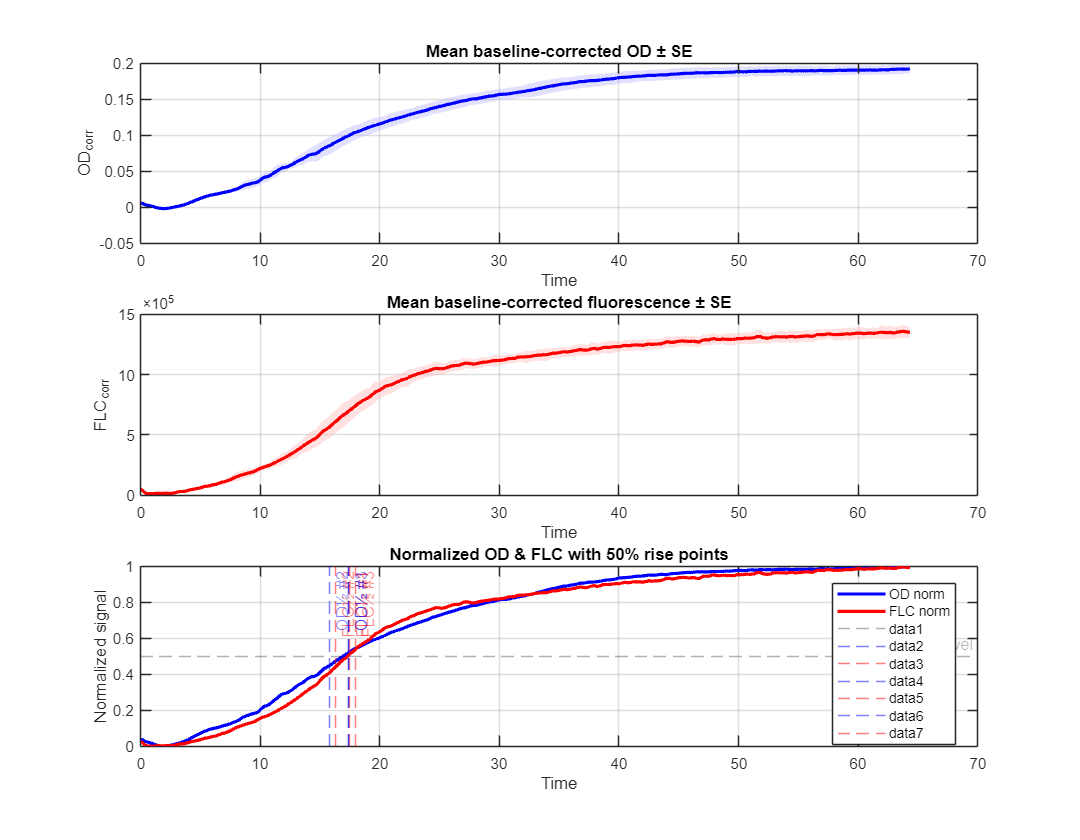


% --- Common time grid (identical across replicates)
t  = results(1).t_series(:);
nT = numel(t);

% --- Stack OD and FLC for averaging
OD_mat   = nan(nT, nReps);
Flc_mat  = nan(nT, nReps);
ODn_mat  = nan(nT, nReps);
Flcn_mat = nan(nT, nReps);

for r = 1:nReps
    tr = results(r).t_series(:);
    if numel(tr) ~= nT || any(tr ~= t)
        error('Time grids differ across replicates. Expected identical t.');
    end
    OD_mat(:,r)   = results(r).OD_corr_s(:);
    Flc_mat(:,r)  = results(r).Flc_corr_s(:);
    ODn_mat(:,r)  = results(r).OD_norm(:);
    Flcn_mat(:,r) = results(r).Flc_norm(:);
end

% --- Compute means ± SE
OD_mean   = mean(OD_mat,  2, 'omitnan');
OD_se     = std( OD_mat,  0, 2, 'omitnan'); 
Flc_mean  = mean(Flc_mat, 2, 'omitnan');
Flc_se    = std( Flc_mat, 0, 2, 'omitnan'); 

ODn_mean  = mean(ODn_mat,  2, 'omitnan');
ODn_se    = std( ODn_mat,  0, 2, 'omitnan'); 
Flcn_mean = mean(Flcn_mat, 2, 'omitnan');
Flcn_se   = std( Flcn_mat, 0, 2, 'omitnan');

% --- 1) Baseline-corrected OD with SE band
figure('Name','Triplicate Averages','Position',[200 200 900 700]);

subplot(3,1,1)
fill([t; flipud(t)], [OD_mean-OD_se; flipud(OD_mean+OD_se)], ...
     [0.7 0.7 1], 'EdgeColor','none','FaceAlpha',0.4); hold on
plot(t, OD_mean, 'b-', 'LineWidth',2);
xlabel('Time'); ylabel('OD_{corr}');
title('Mean baseline-corrected OD ± SE');
grid on

% --- 2) Baseline-corrected fluorescence with SE band
subplot(3,1,2)
fill([t; flipud(t)], [Flc_mean-Flc_se; flipud(Flc_mean+Flc_se)], ...
     [1 0.7 0.7], 'EdgeColor','none','FaceAlpha',0.4); hold on
plot(t, Flc_mean, 'r-', 'LineWidth',2);
xlabel('Time'); ylabel('FLC_{corr}');
title('Mean baseline-corrected fluorescence ± SE');
grid on

% --- 3) Normalized traces with 50% rise markers
subplot(3,1,3)
plot(t, ODn_mean,  'b-', 'LineWidth',2, 'DisplayName','OD norm'); hold on
plot(t, Flcn_mean, 'r-', 'LineWidth',2, 'DisplayName','FLC norm');
yline(0.5,'k--','0.5 level','Alpha',0.3);

% 50% rise markers for each replicate (if present)
for r = 1:nReps
    if isfield(results(r),'t_half_OD')  && ~isempty(results(r).t_half_OD)  && ~isnan(results(r).t_half_OD)
        xline(results(r).t_half_OD,  '--b', sprintf('OD½ #%d',r),  'Alpha',0.5);
    end
    if isfield(results(r),'t_half_Flc') && ~isempty(results(r).t_half_Flc) && ~isnan(results(r).t_half_Flc)
        xline(results(r).t_half_Flc, '--r', sprintf('FLC½ #%d',r), 'Alpha',0.5);
    end
end
xlabel('Time'); ylabel('Normalized signal');
legend('Location','best');
title('Normalized OD & FLC with 50% rise points');
grid on

clf

%% ===============================================================
%  Plot average FLC/OD ratio (mean of replicates) and rate metrics
% ===============================================================

fprintf('\n========== Plotting mean FLC/OD ratio ==========\n');


========== Plotting mean FLC/OD ratio ==========


%%%%%%%%%TIME INPUT%%%%%%%%%%%%%%%%%
% Extract ratio data from each replicate over the analyzed interval
t_ratio_start = 9.5;   % match analyze_one_rep.m
t_ratio_end   = 24;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% All replicates share same t grid
t_all = results(1).t_series(:);
mask_interval = (t_all >= t_ratio_start) & (t_all <= t_ratio_end);

% Build replicate matrix of ratio traces (FLC_corr / OD_corr)
ratio_mat = nan(sum(mask_interval), nReps);
for r = 1:nReps
    ratio = results(r).Flc_corr_s ./ results(r).OD_corr_s;
    ratio_mat(:,r) = ratio(mask_interval);
end

% Compute mean ± SE across replicates
t_fit = t_all(mask_interval);
y_fit = mean(ratio_mat, 2, 'omitnan');
y_se  = std(ratio_mat, 0, 2, 'omitnan'); 

% --- Compute SG derivative (same logic as in analyze_one_rep.m) ---
order = 2;
frame = min(5, 2*floor(numel(t_fit)/4)+1);
frame = max(frame, order+1 + mod(order+1,2));
frame = min(frame, numel(t_fit) - ~mod(numel(t_fit),2));
if mod(frame,2)==0, frame = frame-1; end
ok_sg = frame >= (order+1) && frame <= numel(y_fit) && frame >= 3;

dy_dt = nan(size(y_fit));
avg_rate_sg = NaN;
t_peak_center = NaN;
if ok_sg
    y_sg = sgolayfilt(y_fit, order, frame);
    [~, g] = sgolay(order, frame);
    half = (frame-1)/2;
    dt = median(diff(t_fit));
    for n = (half+1):(numel(y_fit)-half)
        dy_dt(n) = dot(g(:,2), y_sg(n-half:n+half)) / dt;
    end
    avg_rate_sg = trapz(t_fit(~isnan(dy_dt)), dy_dt(~isnan(dy_dt))) ...
                  / (t_fit(end) - t_fit(1));
    [~, idx_peak] = max(dy_dt, [], 'omitnan');
    if ~isempty(idx_peak) && ~isnan(idx_peak)
        t_peak_center = t_fit(idx_peak);
    end
end

% --- Compute spline fit and mean slope ---
pp = csaps(t_fit, y_fit, 0.95);
avg_rate_spline = (fnval(pp, t_fit(end)) - fnval(pp, t_fit(1))) / ...
                  (t_fit(end) - t_fit(1));


figure('Name','Average FLC/OD and rate metrics','Position',[250 250 900 600]);
tiledlayout(2,1,'TileSpacing','compact');

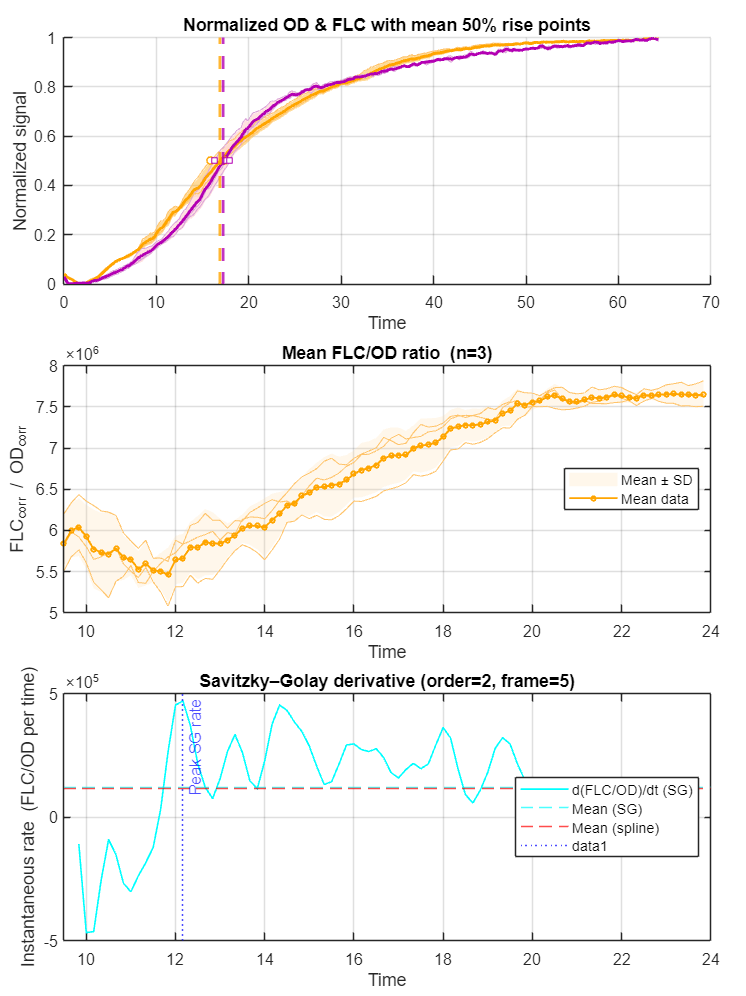


figure('Name','Normalized + FLC/OD Metrics','Position',[250 250 675 900]);
tiledlayout(3,1,'TileSpacing','compact','Padding','compact');

ax0 = nexttile(1);
hold on


fill([t; flipud(t)], ...
     [ODn_mean - ODn_se; flipud(ODn_mean + ODn_se)], ...
     [255/255, 165/255, 0/255], 'EdgeColor','none', 'FaceAlpha',0.4, ...
     'DisplayName','OD norm ± SD');


fill([t; flipud(t)], ...
     [Flcn_mean - Flcn_se; flipud(Flcn_mean + Flcn_se)], ...
     [1.0 0.85 0.85], 'EdgeColor','none', 'FaceAlpha',0.8, ...
     'DisplayName','FLC norm ± SD');

% Individual replicate trajectories (journal transparency requirement).
for r = 1:nReps
    plot(t, ODn_mat(:,r), '-', 'Color', [1.00 0.77 0.42], ...
        'LineWidth', 0.65, 'HandleVisibility','off');
    plot(t, Flcn_mat(:,r), '-', 'Color', [0.86 0.65 0.86], ...
        'LineWidth', 0.65, 'HandleVisibility','off');
end


plot(t, ODn_mean,  '-', 'LineWidth', 1.8, 'DisplayName','NAME OD_{600} mean', 'Color', [255/255, 165/255, 0/255]);
plot(t, Flcn_mean, '-', 'LineWidth', 1.8, 'DisplayName','NAME fluorescence mean', 'Color', [0.7 0.0 0.7]);



t_half_OD_all  = [results.t_half_OD];
t_half_Flc_all = [results.t_half_Flc];
t_half_OD_mean  = mean(t_half_OD_all(~isnan(t_half_OD_all)));
t_half_Flc_mean = mean(t_half_Flc_all(~isnan(t_half_Flc_all)));


validOD  = ~isnan(t_half_OD_all);
validFlc = ~isnan(t_half_Flc_all);
plot(t_half_OD_all(validOD),  0.5*ones(1,sum(validOD)),  'o', ...
    'LineStyle','none', 'MarkerSize',4.5, 'MarkerFaceColor','w', ...
    'MarkerEdgeColor',[255/255,165/255,0], 'LineWidth',0.9, 'HandleVisibility','off');
plot(t_half_Flc_all(validFlc), 0.5*ones(1,sum(validFlc)), 's', ...
    'LineStyle','none', 'MarkerSize',4.5, 'MarkerFaceColor','w', ...
    'MarkerEdgeColor',[0.7 0 0.7], 'LineWidth',0.9, 'HandleVisibility','off');


xline(t_half_OD_mean,  '--',  ...
      'Alpha',0.8, 'LineWidth',1.8, 'Color', [255/255, 165/255, 0/255]);
xline(t_half_Flc_mean, '--', ...
      'Alpha',0.8, 'LineWidth',1.8, 'Color', [0.7 0.0 0.7]);

xlabel('Time');
ylabel('Normalized signal');
%legend('Location','best');
title('Normalized OD & FLC with mean 50% rise points');

ylim([0.0 1.0]);
grid on;

%% ----------FLC/OD ratio ----------
ax1 = nexttile(2);
fill([t_fit; flipud(t_fit)], [y_fit - y_se; flipud(y_fit + y_se)], ...
    [1 0.85 0.6], 'EdgeColor','none', 'FaceAlpha',0.20, 'DisplayName','Mean ± SD'); hold on
for r = 1:nReps
    plot(t_fit, ratio_mat(:,r), '-', 'Color',[1.00 0.77 0.42], ...
        'LineWidth',0.65, 'HandleVisibility','off');
end
p1 = plot(t_fit, y_fit, '-o', 'Color','#FFA500', 'LineWidth',1.2, ...
    'MarkerSize',2.8, 'DisplayName','Mean data');
grid on;
xlabel('Time');
ylabel('FLC_{corr} / OD_{corr}');
title(sprintf('Mean FLC/OD ratio  (n=%d)', nReps));
legend('Location','east');

% ==== EXPORT: mean data + SD + spline values (spline retained for analysis; not plotted) ====

flc_od_tbl = table( ...
    t_fit, ...
    y_fit, ...
    y_se, ...                       
    fnval(pp, t_fit), ...           
    'VariableNames', {'time','mean_FLC_OD','SD_FLC_OD','spline_FLC_OD'});
flc_od_tbl = [flc_od_tbl array2table(ratio_mat, 'VariableNames', repVarNames)];
writetable(flc_od_tbl, 'FLC_OD_mean_plotdata.csv');

%% ---------- BOTTOM PANEL: SG derivative ----------
ax2 = nexttile(3);
plot(t_fit, dy_dt, 'c-', 'LineWidth',1, 'DisplayName','d(FLC/OD)/dt (SG)'); hold on
yline(avg_rate_sg,'--c','DisplayName','Mean (SG)');
yline(avg_rate_spline,'--r','DisplayName','Mean (spline)');
if ~isnan(t_peak_center)
    xline(t_peak_center,':b','Peak SG rate');
end
grid on
xlabel('Time');
ylabel('Instantaneous rate  (FLC/OD per time)');
title(sprintf('Savitzky–Golay derivative (order=%d, frame=%d)', order, frame));
legend('Location','east');

% ==== EXPORT: derivative-related data for second plot ====
mean_sg_vec      = repmat(avg_rate_sg,     size(t_fit));
mean_spline_vec  = repmat(avg_rate_spline, size(t_fit));

deriv_tbl = table( ...
    t_fit, ...
    dy_dt, ...
    mean_sg_vec, ...
    mean_spline_vec, ...
    'VariableNames', {'time','SG_derivative','mean_SG','mean_spline'});
writetable(deriv_tbl, 'FLC_OD_derivative_plotdata.csv');

% optional: export peak SG time (vertical line) if present
if ~isnan(t_peak_center)
    peak_tbl = table(t_peak_center, 'VariableNames', {'t_peak_SG'});
    writetable(peak_tbl, 'FLC_OD_peak_SG.csv');
end

%% ---------- Link only bottom two panels ----------
linkaxes([ax1 ax2],'x');
%% ---------- Link only bottom two panels ----------
linkaxes([ax1 ax2],'x');
xlim([t_ratio_start t_ratio_end]);  % On the current axes; you can explicitly pass ax1 if you want

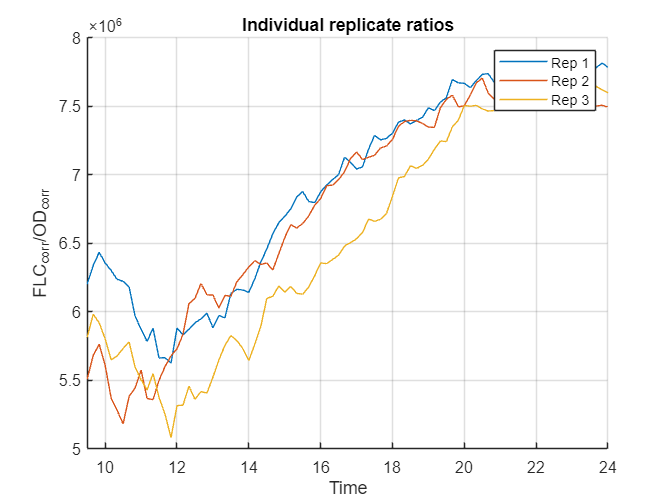


figure;
hold on; 
for r = 1:nReps
    ratio = results(r).Flc_corr_s ./ results(r).OD_corr_s;
    plot(results(r).t_series, ratio, 'DisplayName', sprintf('Rep %d', r));
end
xlabel('Time'); ylabel('FLC_{corr}/OD_{corr}');
xlim([t_ratio_start t_ratio_end]);
title('Individual replicate ratios');
legend show; grid on;

%%%CV >> 1 means mismatched polarity for replicate averages is probably blowing up your SE
%Inpsect triplicate_metrics.csv if this is the case
for i = 1:numel(metricNames)
    vec = [results.(metricNames{i})];
    meanVals(i) = mean(vec, 'omitnan');
    seVals(i)   = std(vec, 0, 'omitnan');
    cv = std(vec, 0, 'omitnan') / abs(meanVals(i));
    fprintf('%-22s = %12.6g ± %.6g (n=%d)   [CV = %.2f]\n', ...
            metricNames{i}, meanVals(i), seVals(i), nReps, cv);
end

avg_rate_sg            =       118414 ± 16331.9 (n=3)   [CV = 0.14]
avg_rate_sg_mean       =       121949 ± 15550.6 (n=3)   [CV = 0.13]
avg_rate_spline        =       117916 ± 12760.6 (n=3)   [CV = 0.11]
avg_rate_spline_int    =       117916 ± 12760.4 (n=3)   [CV = 0.11]
first_valid_ratio_time =            0 ± 0 (n=3)   [CV = NaN]
frac_masked_ratio      =            0 ± 0 (n=3)   [CV = NaN]
lead_half              =    -0.353752 ± 0.263149 (n=3)   [CV = 0.74]
n_masked_ratio         =            0 ± 0 (n=3)   [CV = NaN]
peak_rate_sg           =       701353 ± 69509.1 (n=3)   [CV = 0.10]
t_half_Flc             =      17.2197 ± 0.860925 (n=3)   [CV = 0.05]
t_half_OD              =       16.866 ± 0.903907 (n=3)   [CV = 0.05]
t_peak_center          =      13.6113 ± 1.25109 (n=3)   [CV = 0.09]
t_peak_end             =      13.9444 ± 1.25093 (n=3)   [CV = 0.09]
t_peak_start           =      13.2778 ± 1.25093 (n=3)   [CV = 0.09]
tau_deriv              =     0.388889 ± 0.822147 (n=3)   [CV = 2.1

flc_span = 1486100

rate = 8.1839e+03

hemepercellperhour = 7.6530e+03

pnasmu = 0.1500

pnasrate = 7.5000e+05

factoroff = 0.0065